numero_sensores = 8;
numero_colunas = size(Cap_board_data,2);
numero_amostras = height(Cap_board_data);

Calibracao = [];
AA =[];
B =[];
CC =[];
C = [];
for i = 1:(numero_sensores)
    Calibracao(1,i) = mean(Cali(:,i));
end

% %Reorganiza as colunas
B = [];
i = 1;
C = Cap_board_data;
for k=1:numero_colunas
    m = mod(k,numero_sensores);
    if m == 0
        m=8;
    end
    AA(:,k) = C(:,k) - Calibracao(:,m);
    CC(:,k) = C(:,k) - mean(C(:,k));
end

%j= [1,9,17,25,33];
%j=[2,10,18,26,34];
%j = [8,16,24,32,40];
CC(:,j) = [];
AA(:,j) = [];


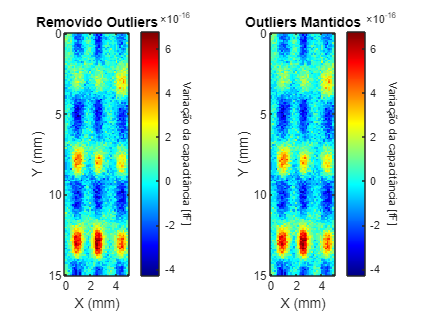

% Fill outliers
[CCC,outlierIndices2] = filloutliers(CC,"linear","gesd", ...
    "ThresholdFactor",0.25);

x=linspace(0,(numero_colunas/numero_sensores),numero_colunas);
x = round(x);
y=linspace(0,numero_amostras,height(Cap_board_data))/10;
y=round(y);
figure
tiledlayout(1,2)
nexttile
imagesc(x,y,CCC)
pbaspect([1 1 1])
pbaspect([numero_colunas/(numero_amostras) 1 1])
title("Removido Outliers")
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")
nexttile
imagesc(x,y,CC)
title("Outliers Mantidos")
%pbaspect([1 1 1])
pbaspect([numero_colunas/(numero_amostras) 1 1])
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")



% Fill outliers
[CCC,outlierIndices] = filloutliers(CC,"linear","gesd", ...
    "ThresholdFactor",0.25);


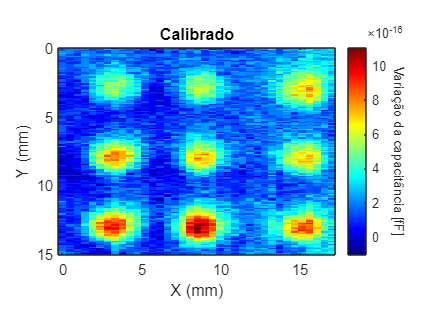

% Fill outliers
[AAA,outlierIndices3] = filloutliers(AA,"linear","gesd", ...
    "ThresholdFactor",0.25);

x=linspace(0,16.5,numero_colunas);
x = round(x);
y=linspace(0,numero_amostras,height(AA))/10;
y=round(y);
figure
nexttile
imagesc(x,y,AAA)
pbaspect([1 1 1])
pbaspect([numero_colunas*5/(numero_amostras) 1 1])
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
title("Calibrado")
xlabel ("X (mm)")
ylabel ("Y (mm)")